% Load Data
clear all;
close all;

## Find Noise Variance

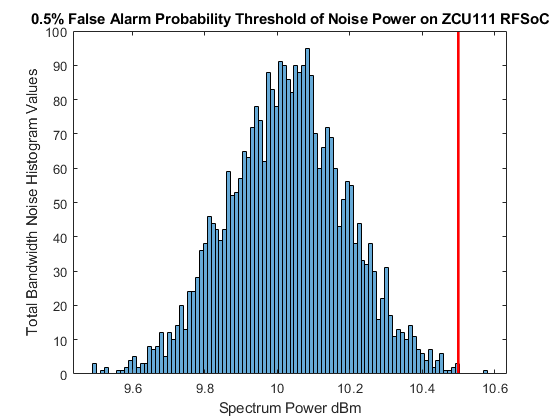

% Load Noise data and calibrate noise floor
noise = load('IQ_samples/SNR_-55/IQ_no_TD.mat');
noise_data = noise.IQcplx_no_td;
data_no_sig = zeros(1024,2,length(noise_data)/1024*100);
data_no_sig(:,1,:) = reshape(noise_data(:,1,:), [1024,length(noise_data)/1024*100]);
data_no_sig(:,2,:) = reshape(noise_data(:,2,:), [1024,length(noise_data)/1024*100]);
data = complex(data_no_sig(:,1,:),data_no_sig(:,2,:));
data_size = size(data);
noise_iq = reshape(data,[data_size(1) data_size(3)]).';
noise_mag = sum(abs(noise_iq),2);


histogram(noise_mag,100)
xlabel('Spectrum Power dBm');
ylabel('Total Bandwidth Noise Histogram Values');
title('0.5% False Alarm Probability Threshold of Noise Power on ZCU111 RFSoC');
line([10.5, 10.5], ylim, 'LineWidth', 2, 'Color', 'r');

## Determine Probabilty of Detection

load trainedNet_real
snr_arr = [-26 -25 -24 -23 -22 -21 -20 -19 -18 -17 -16 -15 -14 -13 -12 -11 -10 -9 -8 -7 -6 -5];
Pd_arr = [];
Pd_arr_nn = [];
for snr=snr_arr
    snr
    
    % Mould the data :)
    file_str = 'IQ_samples/SNR_' + string(snr) + '/IQ_no_TD.mat';
    data = load(file_str);
    data = data.IQcplx_no_td;
    data_iq = zeros(1024,2,length(data)/1024*100);
    data_iq(:,1,:) = reshape(data(:,1,:), [1024,length(data)/1024*100]);
    data_iq(:,2,:) = reshape(data(:,2,:), [1024,length(data)/1024*100]);
    
    % Run energy Detection
    data_iq_complex = complex(data_iq(:,1,:),data_iq(:,2,:));
    data_size = size(data_iq_complex);
    data_iq_complex = reshape(data_iq_complex,[data_size(1) data_size(3)]).';
    data_mag = sum(abs(data_iq_complex),2);
    
    Pd_tot = sum(data_mag > 10.5)/length(data_mag)*100
    Pd_arr = [Pd_arr Pd_tot];
    
    
    % Run NN Detection 
    data_sig_shaped = zeros(1,1024,2,data_size(3));
    data_sig_shaped(:) = data_iq;
    predLabels = trainedNet_real.classify(data_sig_shaped);
    Pd_nn = sum(predLabels == categorical(1))/length(predLabels)*100
    Pd_arr_nn = [Pd_arr_nn Pd_nn];
    
end

snr = -26

Pd_tot = 0.2188

Pd_nn = 20.5625

snr = -25

Pd_tot = 0.2813

Pd_nn = 20.9375

snr = -24

Pd_tot = 0.5313

Pd_nn = 21.9375

snr = -23

Pd_tot = 0.6250

Pd_nn = 24.5000

snr = -22

Pd_tot = 0.4375

Pd_nn = 25.6875

snr = -21

Pd_tot = 0.5938

Pd_nn = 29.7188

snr = -20

Pd_tot = 0.6563

Pd_nn = 31.4063

snr = -19

Pd_tot = 1.0313

Pd_nn = 38.8750

snr = -18

Pd_tot = 1.3750

Pd_nn = 44.4063

snr = -17

Pd_tot = 1.6875

Pd_nn = 52.0625

snr = -16

Pd_tot = 3.2500

Pd_nn = 60.8438

snr = -15

Pd_tot = 5.3125

Pd_nn = 77.0313

snr = -14

Pd_tot = 8.5938

Pd_nn = 82.5938

snr = -13

Pd_tot = 16.3750

Pd_nn = 92.5625

snr = -12

Pd_tot = 31.9375

Pd_nn = 97.7188

snr = -11

Pd_tot = 53.4063

Pd_nn = 99.6563

snr = -10

Pd_tot = 79.0625

Pd_nn = 100

snr = -9

Pd_tot = 94.8125

Pd_nn = 100

snr = -8

Pd_tot = 99.7813

Pd_nn = 100

snr = -7

Pd_tot = 100

Pd_nn = 100

snr = -6

Pd_tot = 100

Pd_nn = 100

snr = -5

Pd_tot = 100

Pd_nn = 100

save('Pd_arr_real', 'Pd_arr')
save('Pd_arr_nn_real', 'Pd_arr_nn')

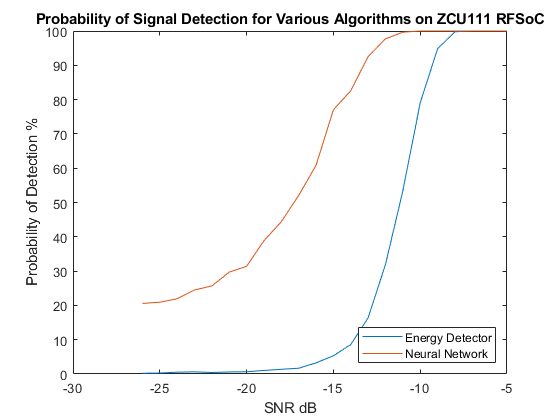

plot(snr_arr, Pd_arr)
hold on
plot(snr_arr, Pd_arr_nn)
hold off
lgd = legend('Energy Detector', 'Neural Network', 'Location', 'southeast');
xlabel('SNR dB');
ylabel('Probability of Detection %');
% title('Probability of Signal Detection for Various Algorithms on ZCU111 RFSoC');